# RECON1 A549 Bulk COBRA Analysis

## Summary

This notebook calculated COBRA solutions using RECON1 for the bulk and single-cell analyses.

## 1. Load up COBRA Toolbox

This code block loads up the COBRA Toolbox for constraint-based metabolic modeling.

clear all;
initCobraToolbox(false); 



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2022
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.29.2).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver('gurobi', 'all');

 > changeCobraSolver: Solver gurobi is installed but not working properly.


Load the RECON1 model and perform setup.

load D:/Chandrasekaran/Projects/eGEM/Data/Reconstructions/RECON1/recon1.mat

Set the objective function to maximize biomass.

model = recon1;
model.c = zeros(size(model.c));
model.c(string(model.rxns) == 'biomass_objective') = 1;

Let's turn off some specific reactions that cause trouble with metabolic models.

%Turn off specific reactions
posToTurnOff           = find(ismember(model.rxns, {'ALR', 'MGSA', 'MGSA2'}));
model.ub(posToTurnOff) = 0; 
model.lb(posToTurnOff) = 0;

Ensure genes are mapped to Entrez.

model.genes = model.geneEntrezID;

## 2. Set flux balance analysis hyperparameters

Assign default values of parameters for the modified iMAT algorithm. This will set the following:

- Kappa (downregulation penalty) = 1

- Rho (upregulation term) = 1

- Epsilon = 1e-3

- Assume maximum parsimony

params = struct();
params.kappa = [];       
params.rho = [];
params.isgenes = true; 
params.pfba = true;
params.epsilon = [];       
params.epsilon2 = [];
params.kappa2 = [];

## 3. Compute COBRA data

This code block fits the metabolic reconstruction with differentially expressed genes using the iMAT algorithm (`constrain_flux_regulation.m`).

%workers = 4;
%parpool("local", workers);
%parpool

### A. Prepare RECON1 data

The expression data used was obtained using the batch correction R notebook. See for details on preprocessing.

exprs = readtable("C:/Users/Scott/Desktop/ComBat_EMT_fitted.csv", 'ReadRowNames', true);
pvalue = readtable("C:/Users/Scott/Desktop/ComBat_EMT_pvalue.csv", 'ReadRowNames', true);

Get the rows that intersect with RECON1

geneids = exprs.Properties.RowNames;
[lia, ~] = ismember(geneids, model.genes);

geneids = geneids(lia);
exprs = exprs(lia, :);
pvalue = pvalue(lia, :);

Get the up and down entrez ids in the `expression` structure for each experiment. Store all the structures in the `all_expression` cell array.

n_expt = size(exprs, 2);
p_thresh = 0.05;
z_thresh = 0;
n_up = zeros();
n_down = zeros();
all_expression = {};
expression = struct();
for j = 1:n_expt
    expt_name = exprs.Properties.VariableNames(j);
    expt_z = table2array(exprs(:, j));
    expt_p = table2array(pvalue(:, j));
    
    expression.upgenes = geneids((expt_z > z_thresh) & (expt_p < p_thresh));
    expression.downgenes = geneids((expt_z < z_thresh) & (expt_p < p_thresh));
    expression.expt_name = expt_name;

    n_up(j) = length(expression.upgenes);
    n_down(j) = length(expression.downgenes);
end

tmp = table2array(exprs);
tmp2 = 2*normpdf(abs(tmp))

tmp2 =     0.7876    0.7765    0.7795    0.7777    0.7831    0.7924    0.7951    0.7909    0.7978    0.7791    0.7964    0.7550    0.6543    0.0528
    0.7979    0.7972    0.7954    0.7878    0.7588    0.6922    0.6945    0.6765    0.5364    0.5989    0.6915    0.5651    0.7582    0.2313
    0.7968    0.7978    0.7975    0.7977    0.7927    0.7923    0.7977    0.7548    0.7521    0.7758    0.7978    0.7849    0.7422    0.2515
    0.7587    0.7567    0.7676    0.7209    0.7327    0.6216    0.7469    0.7974    0.7408    0.7577    0.7090    0.7977    0.7931    0.7074
    0.7974    0.7888    0.7967    0.7866    0.7920    0.7925    0.7966    0.7978    0.7390    0.7862    0.7918    0.7655    0.7961    0.7749
    0.7977    0.7978    0.7976    0.7976    0.7940    0.7819    0.7972    0.7979    0.7636    0.7516    0.7382    0.6528    0.7901    0.7032
    0.7973    0.7979    0.7978    0.7977    0.7979    0.7870    0.7854    0.7811    0.7117    0.7276    0.7811    0.7940    0.7911    0.7470
    0.

sum(tmp2 < 0.05)

ans =      0     0     0     1     0     0     0     0     3     0     0     0     0    15


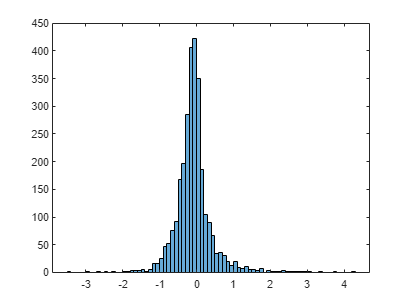

histogram(tmp)

### B. Run RECON1 simulations

Run iMAT for all experiments.

bulk_solns = {};
bulk_models = {};
for j = 1:n_expt
    
    % Fit models and get data
    [model, soln] = CFRv101(model, all_expression{j}, params);
    [geneKO, rxnKO]  = knockOut(model, 'All');
    
    % Save data as individual files
    cobra_cell        = struct();
    cobra_cell.geneko = geneKO;
    cobra_cell.rxnko  = rxnKO;
    cobra_cell.flux   = soln;
    bulk_solns{j} = cobra_cell;
    bulk_models{j} = model;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


Unrecognized function or variable 'cell_mdl'.

save("D:/Chandrasekaran/Projects/EMT/Analysis/COBRA/ComBat/bulk.mat", ...
    'bulk_solns', 'all_expression', 'bulk_models')

### C. Prepare RECON2 data

### D. Run RECON2 Simulations

### E. Prepare RECON3D data

### F. Run RECON3D Simulations

## Summary

This notebook goes through bulk and single cell flux balance analysis. To get differentially active or differentially sensitive metabolic reactions, you can check out the `scDRSA.mlx` file.